# Working with data in MATLAB

# W6 - Topic 2 - Exercise 2

## README

In this prelab, I've already included a lot of the code for each operation. I encourage you to try editing the code for yourself, and seeing how you can change and adapt these examples!

## Keeping track of multiple variables together

Recall from Exercise 1, we computed the sine and cosine at equally spaced intervals and plotted them together.

x = linspace(0, 5*pi, 50)';
y1 = sin(x);
y2 = cos(x);

#### Everything in MATLAB is a matrix...

Notice that these are all *vectors.* In MATLAB, everything is a matrix, so in this case, these variables are 1-dimensional matrices.

disp('The shape of matrix x is: '), size(x)

The shape of matrix x is: 


ans =     50     1


disp('The shape of matrix y1 is: '), size(y1)

The shape of matrix y1 is: 


ans =     50     1


disp('The shape of matrix y2 is: '), size(y2)

The shape of matrix y2 is: 


ans =     50     1


#### Combining matrices (vectors) into a table

Notice also, that these variables are related to each other. It is useful to place these variables into a table so we can keep track of them together.

data = table();
data.x = x;
data.sinx = y1;
data.cosx = y2;

Here are the first few rows of the new table:

first_few_rows = head(data);
display(first_few_rows)

first_few_rows = 8×3 table
       x        sinx        cosx   
    _______    _______    _________

          0          0            1
    0.32057    0.31511      0.94906
    0.64114    0.59811      0.80141
    0.96171    0.82017      0.57212
     1.2823    0.95867      0.28453
     1.6029    0.99949    -0.032052
     1.9234    0.93847     -0.34537
      2.244    0.78183     -0.62349


Although in table format, all the variables maintain their shape (and type). They continue to be 50 x 1 matrices of numbers.

summary(data)

Variables:

    x: 50×1 double

        Values:

            Min             0 
            Median      7.854 
            Max        15.708 

    sinx: 50×1 double

        Values:

            Min       -0.99538
            Median     0.25365
            Max        0.99949

    cosx: 50×1 double

        Values:

            Min               -1
            Median    -2.498e-16
            Max                1



You can also view the table by double-clicking on the table variable the MATLAB Workspace:

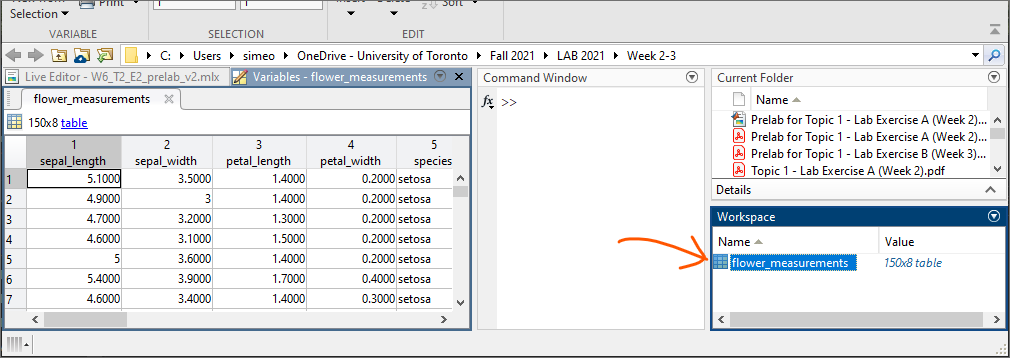

Finally, we can also plot the data from the table:

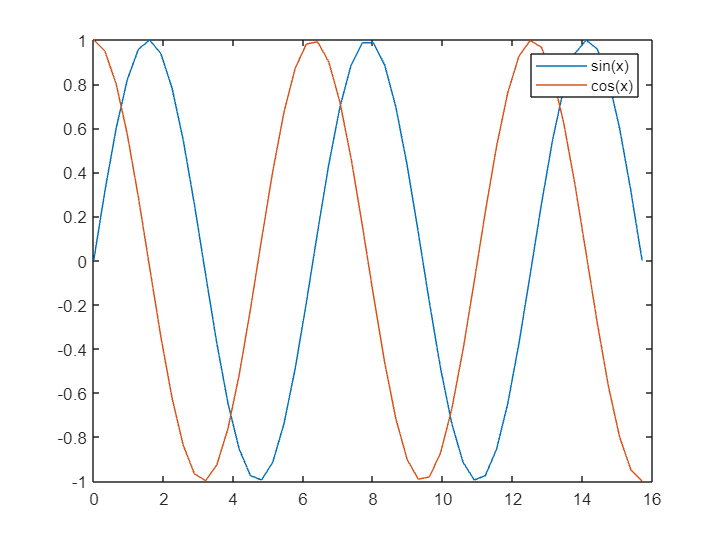

figure;
plot(data.x, data.sinx, data.x, data.cosx)
legend(["sin(x)", "cos(x)"])

## Manipulating data tables

**Reference:** [Access Data in Tables - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

Tables in MATLAB are a neat way to work with datasets. It's a convenient format for many types of datasets like results of experiments or timeseries (ie. stock prices over time).

In this case, let's load some data from a botanical observational experiment where a researcher measured various Iris flowers in the wild.

flower_measurements = readtable('https://raw.githubusercontent.com/mwaskom/seaborn-data/master/iris.csv');
flower_measurements.species = categorical(flower_measurements.species);
display(head(flower_measurements))

  8×5 table

    sepal_length    sepal_width    petal_length    petal_width    species
    ____________    ___________    ____________    ___________    _______

        5.1             3.5            1.4             0.2        setosa 
        4.9               3            1.4             0.2        setosa 
        4.7             3.2            1.3             0.2        setosa 
        4.6             3.1            1.5             0.2        setosa 
          5             3.6            1.4             0.2        setosa 
        5.4             3.9            1.7             0.4        setosa 
        4.6             3.4            1.4             0.3        setosa 
          5             3.4            1.5             0.2        setosa 



We can index tables similar to MATLAB matrices. This will select the first 5 rows. This is useful for sampling some of the raw data as a double-check that we loaded the correct dataset, and loaded the dataset correctly.

flower_measurements(1:5,:)

ans = 5×5 table
    sepal_length    sepal_width    petal_length    petal_width    species
    ____________    ___________    ____________    ___________    _______

        5.1             3.5            1.4             0.2        setosa 
        4.9               3            1.4             0.2        setosa 
        4.7             3.2            1.3             0.2        setosa 
        4.6             3.1            1.5             0.2        setosa 
          5             3.6            1.4             0.2        setosa 


**Use your knowledge of MATLAB indexing to select the last 5 rows of the table:**

% <<< complete this line
flower_measurements(end-4:end,:)

ans = 5×5 table
    sepal_length    sepal_width    petal_length    petal_width     species 
    ____________    ___________    ____________    ___________    _________

        6.7               3            5.2             2.3        virginica
        6.3             2.5              5             1.9        virginica
        6.5               3            5.2               2        virginica
        6.2             3.4            5.4             2.3        virginica
        5.9               3            5.1             1.8        virginica


We can also generate some quick summary statistics on the table:

summary(flower_measurements)

Variables:

    sepal_length: 150×1 double

        Values:

            Min         4.3   
            Median      5.8   
            Max         7.9   

    sepal_width: 150×1 double

        Values:

            Min           2   
            Median        3   
            Max         4.4   

    petal_length: 150×1 double

        Values:

            Min            1  
            Median      4.35  
            Max          6.9  

    petal_width: 150×1 double

        Values:

            Min         0.1   
            Median      1.3   
            Max         2.5   

    species: 150×1 categorical

        Values:

            setosa           50   
            versicolor       50   
            virginica        50   



Let's find out how many different species of flowers were measured:

unique(flower_measurements.species)

ans = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


We can also assign new variables in the table. In this case, all the length measurements are in inches, but since we're in Canada, we should convert them to metric.

flower_measurements.petal_width_cm = flower_measurements.petal_width * 2.54;
flower_measurements.sepal_length_cm = flower_measurements.sepal_length * 2.54;
flower_measurements.sepal_width_cm = flower_measurements.sepal_width * 2.54;

head(flower_measurements)  % show first few rows to check we did the calculation correctly

ans = 8×8 table
    sepal_length    sepal_width    petal_length    petal_width    species    petal_width_cm    sepal_length_cm    sepal_width_cm
    ____________    ___________    ____________    ___________    _______    ______________    _______________    ______________

        5.1             3.5            1.4             0.2        setosa         0.508             12.954              8.89     
        4.9               3            1.4             0.2        setosa         0.508             12.446              7.62     
        4.7             3.2            1.3             0.2        setosa         0.508             11.938             8.128     
        4.6             3.1            1.5             0.2        

**Your turn: convert the **`petal_length`** variable to centimeters and store this into the variable **`petal_length_cm`**:**

% <<< complete this line
flower_measurements.petal_length_cm = flower_measurements.petal_length * 2.54;
head(flower_measurements)

ans = 8×9 table
    sepal_length    sepal_width    petal_length    petal_width    species    petal_width_cm    sepal_length_cm    sepal_width_cm    petal_length_cm
    ____________    ___________    ____________    ___________    _______    ______________    _______________    ______________    _______________

        5.1             3.5            1.4             0.2        setosa         0.508             12.954              8.89              3.556     
        4.9               3            1.4             0.2        setosa         0.508             12.446              7.62              3.556     
        4.7             3.2            1.3             0.2        setosa         0.50

#### Visualization

Finally, we can run analyses like plotting the different variables against each other:

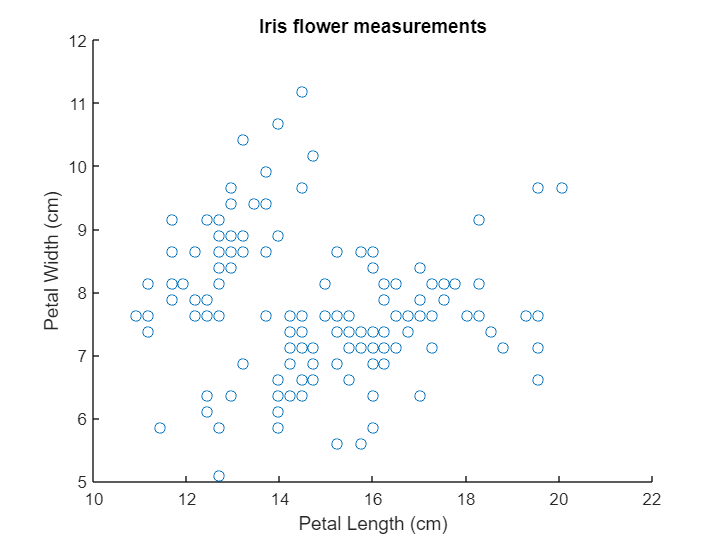

figure;
scatter(flower_measurements, "sepal_length_cm", "sepal_width_cm")
title('Iris flower measurements')
ylabel('Petal Width (cm)')
xlabel('Petal Length (cm)')

Notice how there seems like there are two distinct "blobs" of points. Recall that there were 3 different species of Iris flowers. Perhaps we should plot them in different colours.

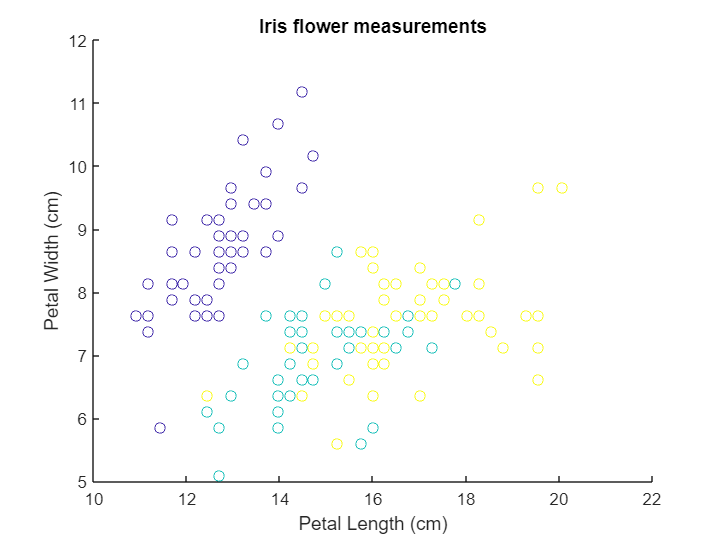

figure;
%                                                                    ↓↓↓↓↓↓↓  NEW  ↓↓↓↓↓↓↓
scatter(flower_measurements, "sepal_length_cm", "sepal_width_cm", "ColorVariable", "species")
title('Iris flower measurements')
ylabel('Petal Width (cm)')
xlabel('Petal Length (cm)')

This new plot is a lot more meaningful!

**Your turn: Plot the Sepal length vs the Petal length.**

- Make a basic plot of just the length values, with nothing fancy.

- Next, colour each dot based on the species. Bonus: vary the shape by species as well!

- Finally, try adjusting the size of each dot based on the petal width.

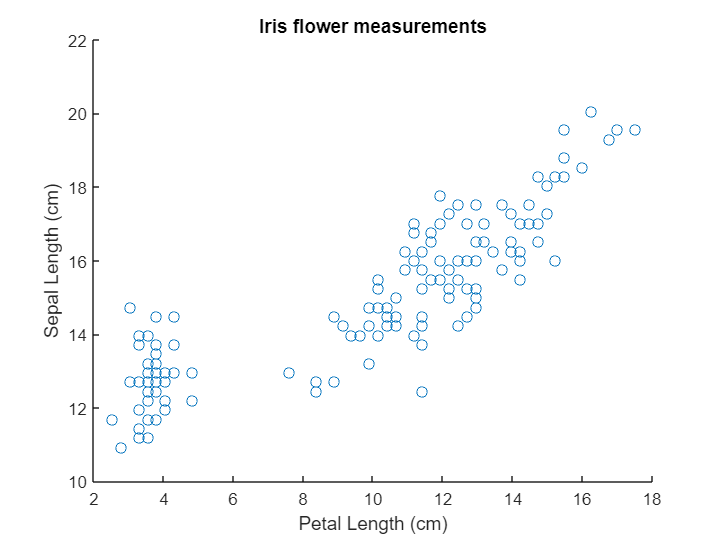

figure;
%%% your code below %%%
scatter(flower_measurements, "petal_length_cm", "sepal_length_cm")
title('Iris flower measurements')
ylabel('Sepal Length (cm)')
xlabel('Petal Length (cm)')


figure;
%%% your code below %%%
s = scatter(flower_measurements, "petal_length_cm", "sepal_length_cm", "ColorVariable", "species")

s =   Scatter with properties:

          XVariable: "petal_length_cm"
          YVariable: "sepal_length_cm"
              ZData: [1×0 double]
           SizeData: 36
      ColorVariable: "species"
             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000

  Show all properties


s.SizeData = flower_measurements.petal_width_cm

s =   Scatter with properties:

          XVariable: "petal_length_cm"
          YVariable: "sepal_length_cm"
              ZData: [1×0 double]
           SizeData: [0.5080 0.5080 0.5080 0.5080 0.5080 1.0160 0.7620 0.5080 0.5080 0.2540 0.5080 0.5080 0.2540 0.2540 0.5080 1.0160 1.0160 0.7620 0.7620 0.7620 0.5080 1.0160 0.5080 1.2700 0.5080 0.5080 1.0160 0.5080 0.5080 0.5080 0.5080 1.0160 … ]
      ColorVariable: "species"
             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000

  Show all properties


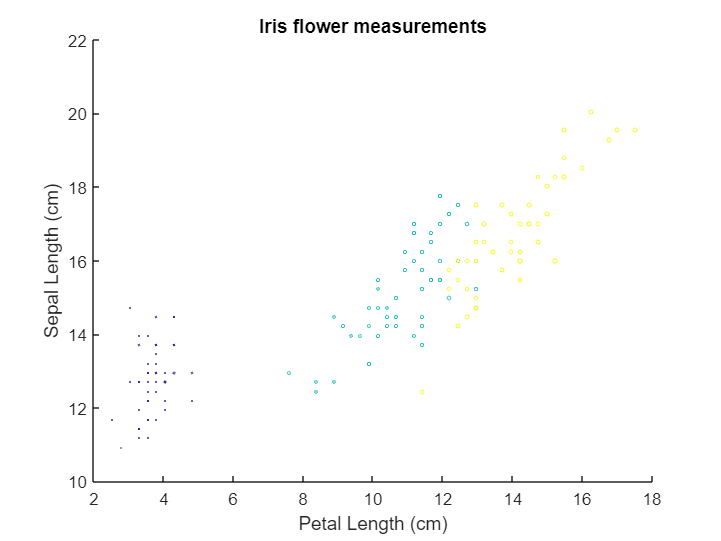

title('Iris flower measurements')
ylabel('Sepal Length (cm)')
xlabel('Petal Length (cm)')

%%%%%%%%%%%%%%%%%%%%%%%

## Polar coordinates and transformations

Although we can do this using transformation matrices as you will learn in lecture, we can use MATLAB to convert between cartesian and polar coordinates.

Some useful functions:

Here, we define two points in Cartesian coordinates:

a = [1; 2];
b = [5; 3];

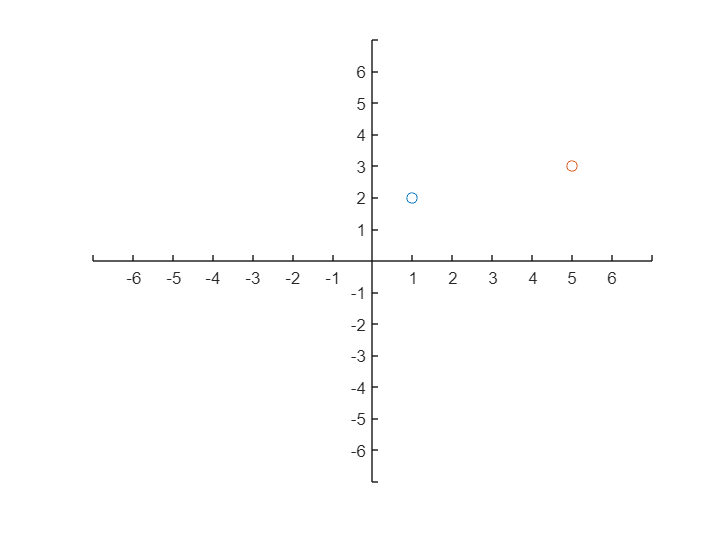

% plotting
figure;
hold on
scatter(a(1), a(2))
scatter(b(1), b(2))

% draw axes for reference
axis([-7, 7, -7, 7]), set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin', 'XTick', -7:7, 'YTick', -7:7)

**Your turn: Represent these points in Polar coordinates and store them into variables **`a_theta, a_rho, b_theta, b_rho`**:**

%%% your code here %%%%
[a_theta,a_rho] = cart2pol(a(1),a(2));
[b_theta,b_rho] = cart2pol(b(1),b(2));
%%%%%%%%%%%%%%%%%%%%%%%

% display your final results
display(a_theta), display(a_rho)

a_theta = 1.1071

a_rho = 2.2361

display(b_theta), display(b_rho)

b_theta = 0.5404

b_rho = 5.8310

**Notice:** What units are theta in? Radians or degrees?

Radians: "Angular coordinate, returned as an array. `theta` is the counterclockwise angle in the *x*-*y* plane measured in radians from the positive *x*-axis. The value of the angle is in the range `[-pi pi]`."

## Polar plots

Now we can try plotting these points in polar coordinates:

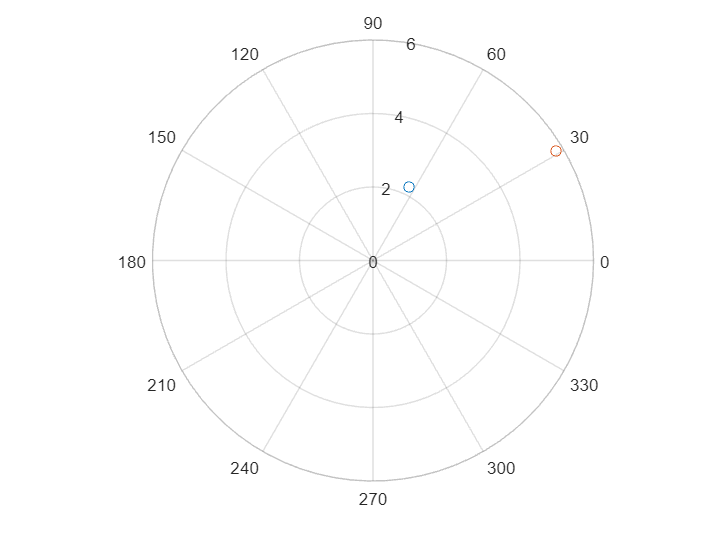

figure;
polarscatter(a_theta, a_rho)
hold on
polarscatter(b_theta, b_rho)

**Change the cartesian coordinates above and rerun this code to see how the values change!**